# Generalized Linear Regression

## Load data and view raw data

In the data from various countrys one can find a correlation (which probably does *not* describe a causal relation) between life expectancy and the number of TVs per capita:

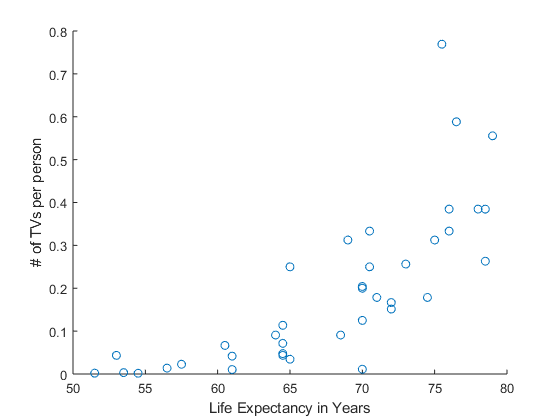

load HealthyTVs.mat

scatter(LifeExp,TV)
xlabel('Life Expectancy in Years')
ylabel('# of TVs per person')

It looks like `log(TV)` depends linearly on `LifeExp`:

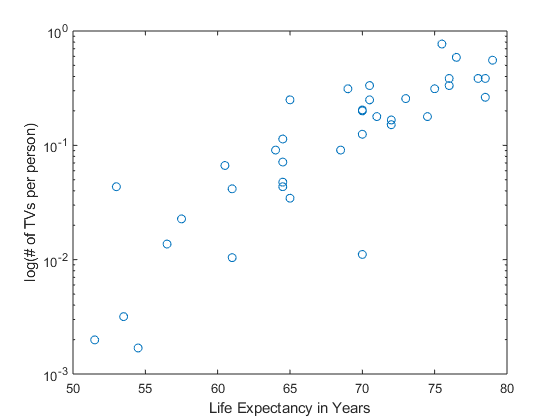

figure
semilogy(LifeExp,TV,'o')
xlabel('Life Expectancy in Years')
ylabel('log(# of TVs per person)')

The distribution of `TV` is positive and right-skewed:

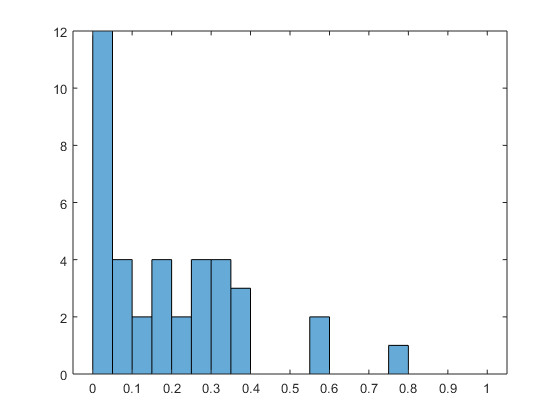

figure
histogram(TV,0:0.05:1)

## Perform generalized linear regression

A typical choice in such a situation is a GLM with a gamma distribution and a log link function:

tvglm = fitglm(LifeExp,TV,'Distribution','gamma',...
    'Link','log','VarNames',{'LifeExp','TV'})

tvglm = Generalized linear regression model:
    log(TV) ~ 1 + LifeExp
    Distribution = Gamma

Estimated Coefficients:
                   Estimate      SE        tStat       pValue  
                   ________    _______    _______    __________
    (Intercept)    -12.038      1.0284    -11.705    7.8823e-14
    LifeExp        0.14657     0.01508     9.7195    1.3213e-11

38 observations, 36 error degrees of freedom
Estimated Dispersion: 0.512
F-statistic vs. constant model: 67.5, p-value = 8.9e-10

Compare the model visually to the data:

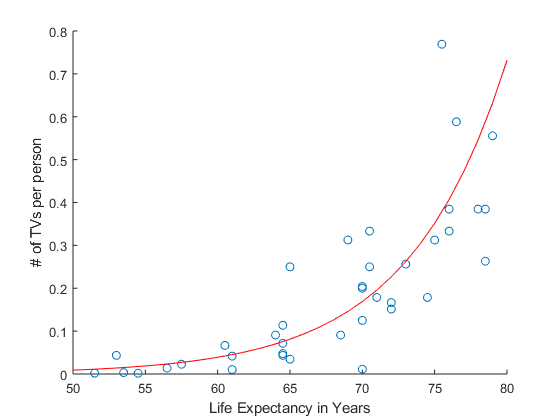

scatter(LifeExp,TV)
xlabel('Life Expectancy in Years')
ylabel('# of TVs per person')

hold on

LEfit = (50:80)';
TVfit = predict(tvglm,LEfit);
plot(LEfit,TVfit,'r')

The log link ensures that the predicted values are all positive.

## Compare with regular linear regression

Do ordinary linear regression on $\log(TV) = \beta_1 + \beta_2\cdot LifeExp$

linfit = fitlm(LifeExp,log(TV))

linfit = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE        tStat       pValue  
                   ________    ________    _______    __________
    (Intercept)    -14.009        1.183    -11.842    5.6385e-14
    x1             0.17166     0.017346     9.8963    8.2005e-12

Number of observations: 38, Error degrees of freedom: 36
Root Mean Squared Error: 0.823
R-squared: 0.731,  Adjusted R-Squared 0.724
F-statistic vs. constant model: 97.9, p-value = 8.2e-12

Add fitted model to plot

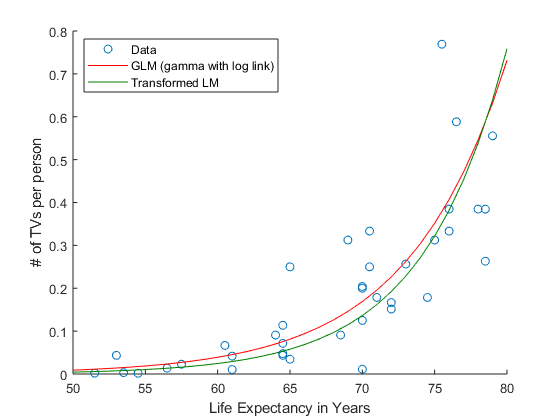

TVfit2 = exp(predict(linfit,LEfit));
plot(LEfit,TVfit2,'Color',[0 0.5 0])
hold off
legend('Data','GLM (gamma with log link)','Transformed LM','location','best')

## View fits in logarithmic axes

This view shows the magnified effect of outliers on regular linear regression (and therefore demonstrates the benefit of using GLM).

Data

semilogy(LifeExp,TV,'o')
hold on

GLM

plot(LEfit,TVfit,'r')

Linear regression & transformation

plot(LEfit,TVfit2,'Color',[0 0.5 0])
xlabel('Life Expectancy in Years')
ylabel('log(# of TVs per person)')

Who are the outliers?

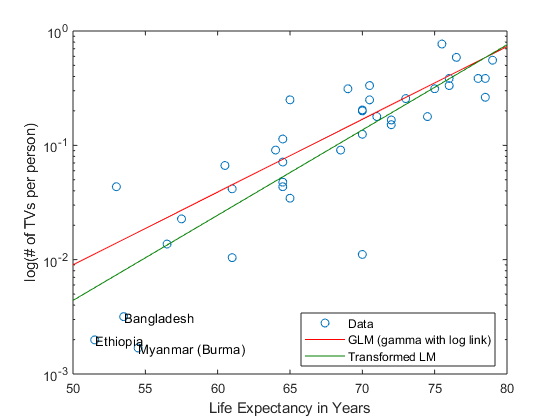

[stv,idx] = sort(TV);
text(LifeExp(idx(1:3)),stv(1:3),country(idx(1:3)))
hold off
legend('Data','GLM (gamma with log link)','Transformed LM','location','best')